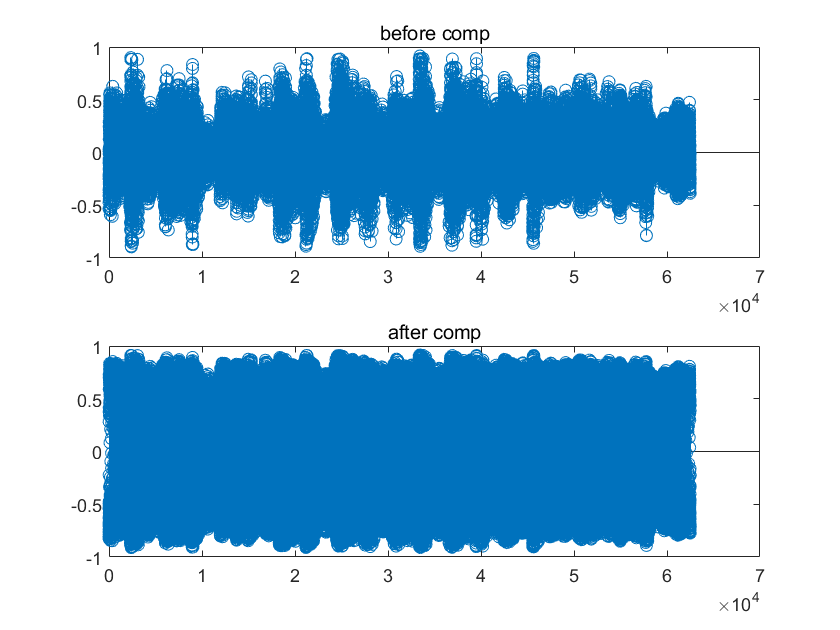

s0 = signal;

% 44.1kHz -> 11.025kHz 1/4배
s1 = s0([1:4:length(s0)]);

% Mu compression(mu = 255)
% compand(sampling된 신호, Mu, ...
% 신호에 가장 큰 크기, compressor or expander)
compS = compand(s1,255,max(abs(s1)),'mu/compressorr');
% plot 한번 그려보기, xlen = length(s1) <- 그냥 숫자임
subplot(2,1,1); stem(s1), title("before comp")
subplot(2,1,2); stem(compS),title("after comp")

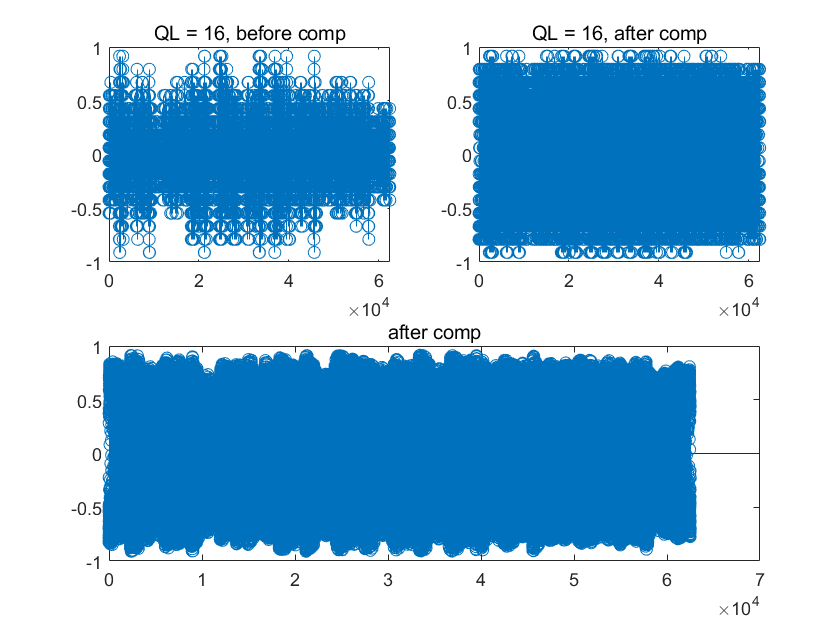


% partition(threshold) and codebook(Quant Level)
% Quantization Level = 16
ql16 = linspace(min(compS),max(compS),16);
th16 = zeros(1,15);
for i = 1:length(ql16)-1
    th16(i)=(ql16(i)+ql16(i+1))/2;
end
[~,quants16_s1] = quantiz(s1,th16,ql16);
[~,quants16_compS] = quantiz(compS,th16,ql16);

% Quantization Level = 256
ql256 = linspace(min(compS),max(compS),256);
th256 = zeros(1,255);
for i = 1:length(ql256)-1;
    th256(i) = (ql256(i)+ql256(i+1))/2;
end
[~,quants256_s1] = quantiz(s1,th256,ql256);
[~,quants256_compS] = quantiz(compS,th256,ql256);
% quants 한 다음 4개 그래프 비교
subplot(2,2,1); stem(quants16_s1), title("QL = 16, before comp")
subplot(2,2,2); stem(quants16_compS), title("QL = 16, after comp")

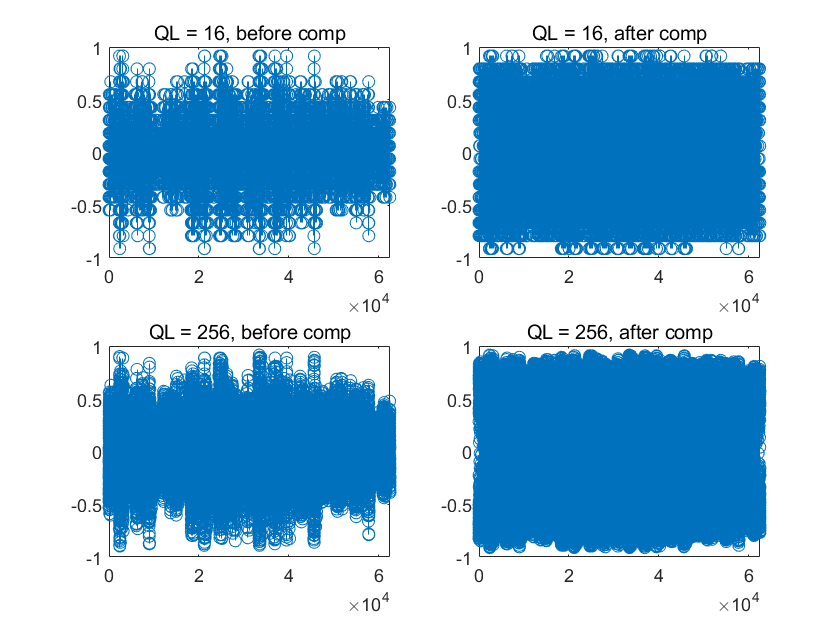

subplot(2,2,3); stem(quants256_s1), title("QL = 256, before comp")
subplot(2,2,4); stem(quants256_compS), title("QL = 256, after comp")

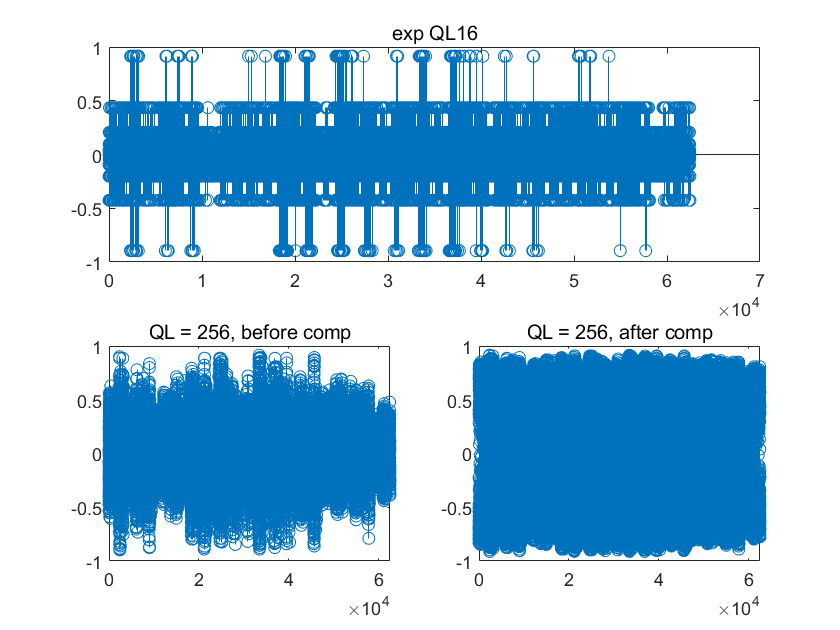


% compand(in,mu,peak magnitude,"mu/expander")
exp16 = compand(quants16_compS,255,max(abs(quants16_compS)),"mu/expander");
exp256 = compand(quants256_compS,255,max(abs(quants256_compS)),"mu/expander");
subplot(2,1,1); stem(exp16), title("exp QL16")

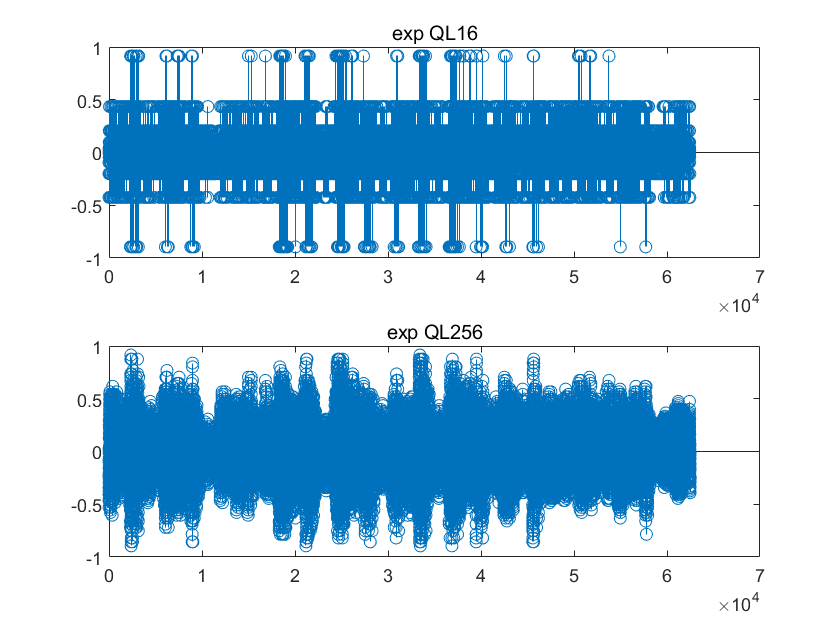

subplot(2,1,2); stem(exp256),title("exp QL256")

% sound 
% (s0,44100),(s1,11025),(compS,11025)
% (quants16_s1,11025),(quants16_compS,11025)
% (quants256_s1,11025),(quants256_compS,11025)
% (exp16,11025),(exp256,11025)
sound(s0,44100)
pause(7)

sound(s1,11025)
pause(7)
sound(compS,11025)
pause(7)
sound(quants16_s1,11025)
pause(7)
sound(quants16_compS,11025)
pause(7)
sound(quants256_s1,11025)
pause(7)
sound(quants256_compS,11025)
pause(7)
sound(exp16,11025)
pause(7)
sound(exp256,11025)